# **Deeplab Image Semantic Segmentation Algorithm**

**Network Generation, Training and Testing**

***S. Gardner, M. R. Haider***

**University of Alabama at Birmingham**

**Autonomous Vehicle Mobility Institution - Army Research Center**

**Updated: March 2023**

This algorithm inputs RELLIS images into DeeplabV3+ for semantic segmentation.

## Set flags

sanityCheck  = true;  % Check Deeplab performance
metricsCheck = true;  % Check Deeplab metrics
trainNew     = true; % Train the Deeplab algorithm

## Source the Datasets

Point to source location of **data**:

inputImagesTrain = 'C:\Users\stevendg\Desktop\UAB PhD\Projects\2020_6 AVML DoD Project\SimulatedSceneExamples\images';
outputTeachTrain = 'C:\Users\stevendg\Desktop\UAB PhD\Projects\2020_6 AVML DoD Project\SimulatedSceneExamples\annotations';

## Output Class Names

classes = ["sky"
           "trail"
           "grass"
           "obstruction"
           ];

#### Input/Teacher Datastores

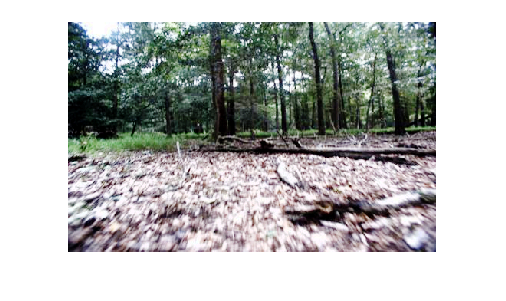

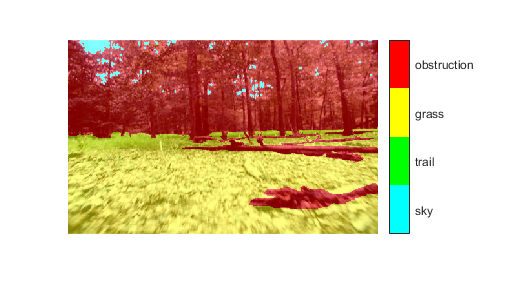

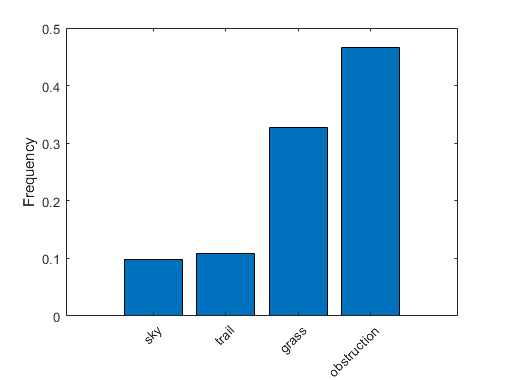

[imdsTrain,pxdsTrain,tblTrain] = generateDatastores(inputImagesTrain, ...
    outputTeachTrain,classes,sanityCheck,metricsCheck);

# Train/Import the Deeplab V3+ Network

#### Color Map

cmap = dataColorMap;

**Generate the Deeplab Network**

Takes several hours if training new net

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:01:24 |       31.51% |       31.72% |       1.7045 |       3.4387 |          0.0010 |
|       1 |           2 |       00:01:37 |       31.92% |              |       3.5717 |              |          0.0010 |
|       1 |           4 |       00:02:04 |       63.57% |              |       0.9106 |              |          0.0010 |
|       1 |           6 |       00:02:29 |       76.77% |              |       0.6937 |              |          0.0010 |
|       1 |           8 |       00:02:55 |       78.08% |              |       0.5817 |              |          0.0010 |
|       1 |          10 |       00:03:20 |       78.89% |              |       0.5539 |              |          0.0010 |
|       1 |          12 |       00:03:45 |       82.57% |              |       0.5076 |              |          0.0010 |
|       1 |          14 |       00:04:10 |       82.34% |              |       0.4936 |              |          0.0010 |
|       1 |          16 |       

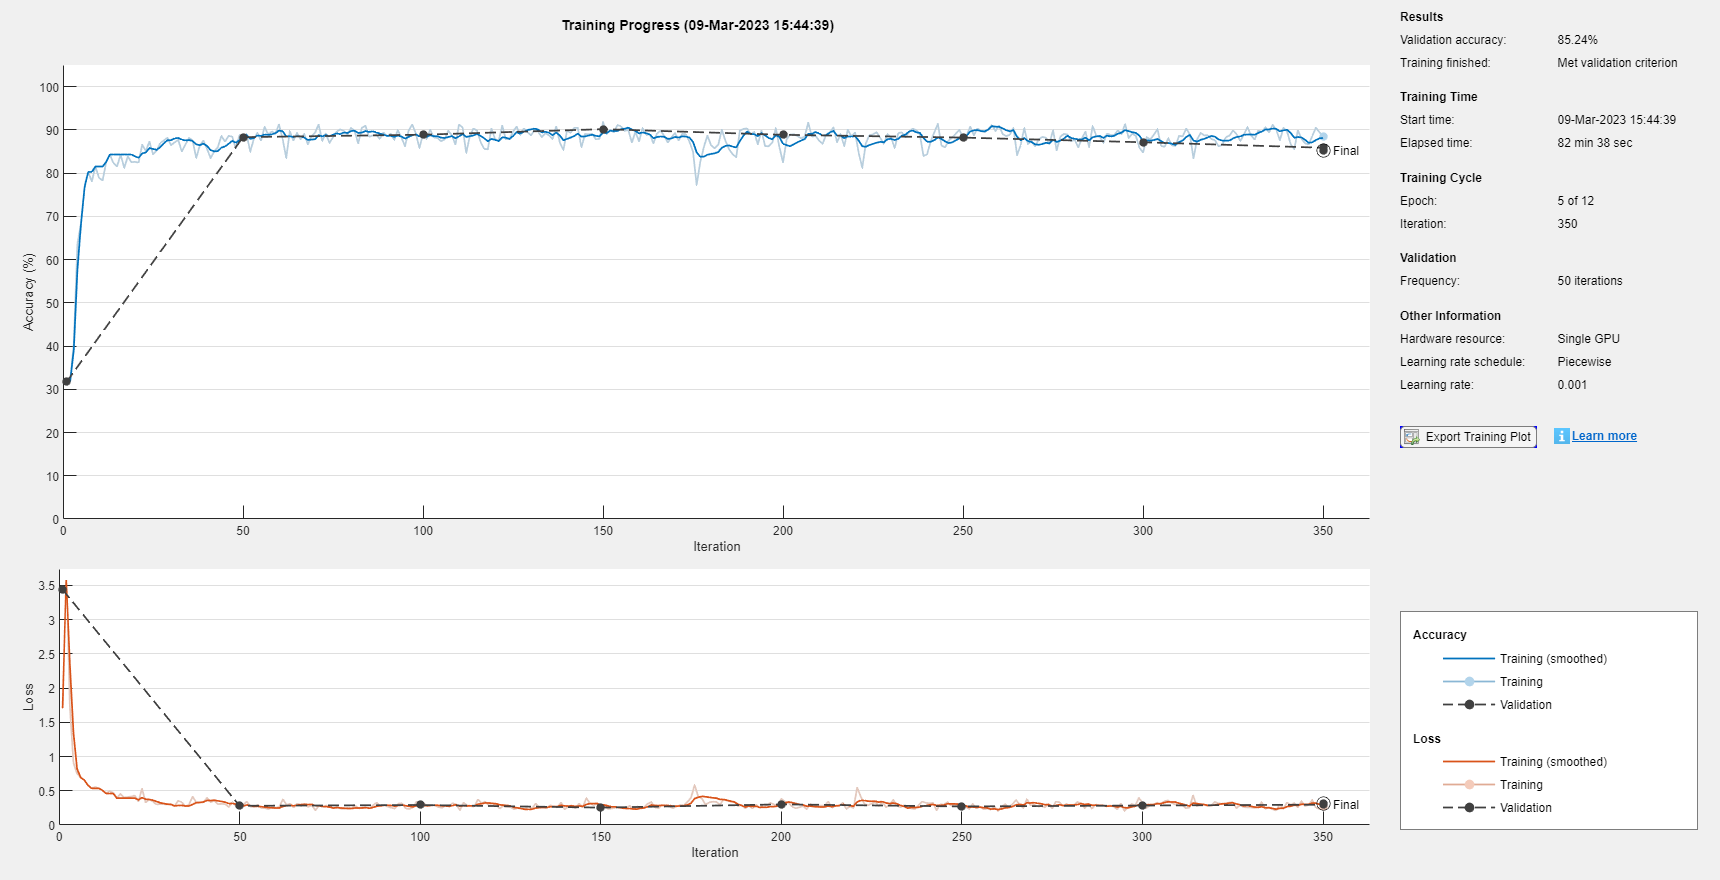

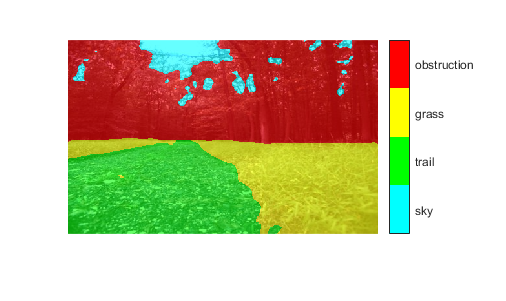

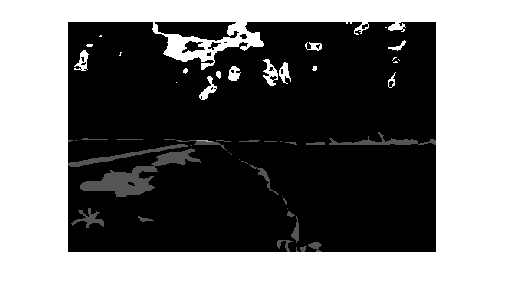

ans = 4×2 table
       classes         iou  
    _____________    _______

    "sky"            0.35441
    "trail"          0.85482
    "grass"          0.83413
    "obstruction"      0.913


ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.85638          0.90026       0.71984      0.75774          NaN    


ans = 4×3 table
                   Accuracy      IoU      MeanBFScore
                   ________    _______    ___________

    sky            0.98918     0.61706          NaN  
    trail          0.95308     0.68962          NaN  
    grass           0.8506     0.79251          NaN  
    obstruction    0.80817     0.78016      0.60023  


net = generateDLN(imdsTrain,pxdsTrain,classes,tblTrain,cmap, ...
    trainNew,sanityCheck,metricsCheck);


if trainNew
    save('dlnet_RUGD_singleTile.mat','net','cmap','classes');
end